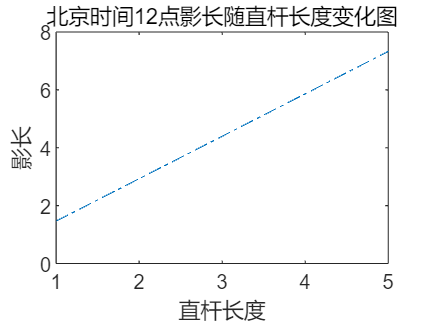

%该文件用来绘制北京时间12点影长随直杆长度变化图

n=n_days(2015,10,22);%根据自定义函数求得n
phi=((39+54/60+26/3600)/180)*2*pi;%由题，北京纬度为39度54分26秒
t=12;%取北京时间12点作为参考量
st_t=t-8+(116+23/60+29/3600)/15;%根据自定义函数转化为当地标准时间
H=((15*(st_t-12))/180)*2*pi;%H为太阳时角
delte=abs((23.45*sin(2*pi*(284+n)/365))/180)*2*pi;%delte为太阳赤纬
L=1:0.1:5;%表示直杆长度

l=zeros(1,size(L,2));%用来存储所求的所有影长
for i=1:size(L,2) 
    alpha=asin(sin(delte)*sin(phi)+cos(delte)*cos(phi)*cos(H));%alpha为太阳光线的入射角度
    l(1,i)=abs(L(i)/tan(alpha));%l表示此时影长
end

figure(1)
plot(L,l,'-.');
title('北京时间12点影长随直杆长度变化图');
xlabel('直杆长度');
ylabel('影长');
xlim([1,5]);